clear all
close all

% GRAPH/DIGRAPH #1/2
Gx=[0 cos(pi/6) -cos(pi/6) 0];
Gy=[1 -0.5 -0.5 0];

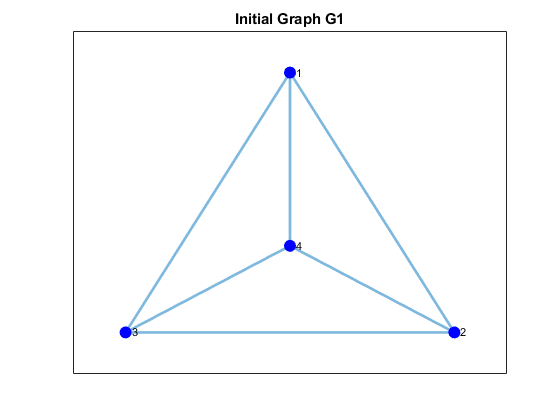

% GRAPH #1
edgesG1 = [ 1 2;
            1 3;
            1 4;
            2 4;
            2 3;
            3 4];
figure; G1 = graph(edgesG1(:,1),edgesG1(:,2));
plot(G1,'XData',Gx,'YData',Gy,'MarkerSize',8,'NodeColor','b', 'LineWidth',2);
xticks([]); yticks([]); title('Initial Graph G1')


% Adjacency matrix
A = [   0 1 1 1;   
        1 0 1 1;   
        1 1 0 1;   
        1 1 1 0];  

% Degree matrix
D = diag([3 3 3 3]);

% Laplacian matrix
L = D-A

L =      3    -1    -1    -1
    -1     3    -1    -1
    -1    -1     3    -1
    -1    -1    -1     3


% CASE 1 
P = eye(4);
sigmaP = eig(P)

sigmaP =      1
     1
     1
     1


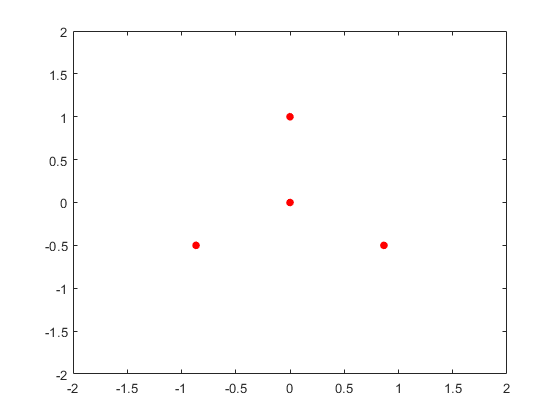

n = 10;


XY = 10 * rand(2,n) - 5;
for i=1:n
    plot(Gx,Gy,'or','MarkerSize',5,'MarkerFaceColor','r')
    axis([-2 2 -2 2])
    pause(1)
end